## Generating the Sine Wav

clear, close all
%% Generate Sine Wave
% This example shows how to use the NCO block to generate
% a sine wave. 
% 
% Copyright 2021 The MathWorks, Inc.

%%
% The example generates a sine wave with these specifications.
%

Fs = 60e6;
Fc = 15e6;
F0 = Fc;        % Desired output frequency (Hz)
Deltaf = 0.05;  % Frequency resolution (Hz)
SFDR = 90;      % Spurious free dynamic range (dB)
Ts = 1/Fs;      % Sample period (s)
phOffd = pi/2;  % Desired phase offset (rad)

N = ceil(log2(1/(Ts*Deltaf))); 
Q = ceil((SFDR - 12)/6);
phIncr = round(F0*2^N*Ts);
phOff = (2^N*phOffd)/(2*pi);
ditherBits = N - Q;


## Low Pass Filter Design

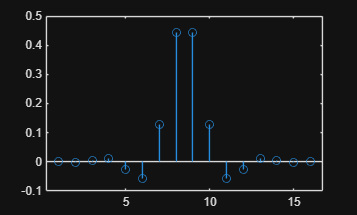

L = 15;         % Filter order -> length = N + 1
Fs = 60e6;
Fc = 15e6;      % Cutoff = Fs/4
Wn = Fc/(Fs/2); % normalized cutoff in (0,1), here 0.5

win = blackman(L+1); 
h = fir1(L, Wn, "low", win, "scale");  % Type I linear-phase lowpass
hf = fi(h,1,12,11);
stem(h)

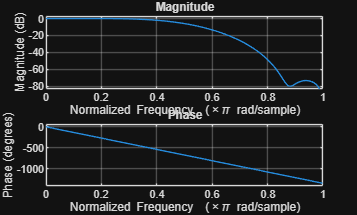

freqz(h)